clc
clear
close all

%Serena Elijah
%AE 426 Project 1 
%Question 1

xdotinitial = -2

xdotinitial = -2

xinitial = 3

xinitial = 3

yinitial = 1

yinitial = 1


r0 = [xinitial; xdotinitial; yinitial] ;

tspan = 1:0.1:8

tspan =     1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000    3.1000    3.2000    3.3000    3.4000    3.5000    3.6000    3.7000    3.8000    3.9000    4.0000    4.1000    4.2000    4.3000    4.4000    4.5000    4.6000    4.7000    4.8000    4.9000    5.0000    5.1000    5.2000    5.3000    5.4000    5.5000    5.6000    5.7000    5.8000    5.9000


[t,r] = ode45(@(t,r) eom(t,r), tspan, r0)

t =     1.0000
    1.1000
    1.2000
    1.3000
    1.4000
    1.5000
    1.6000
    1.7000
    1.8000
    1.9000


r = 	1.0e+05 *

    0.0000   -0.0000    0.0000
    0.0000   -0.0000    0.0000
    0.0000   -0.0000    0.0000
    0.0000   -0.0000    0.0000
    0.0000   -0.0001    0.0000
    0.0000   -0.0001    0.0000
    0.0000   -0.0001    0.0001
   -0.0000   -0.0001    0.0001
   -0.0000   -0.0001    0.0001
   -0.0000   -0.0002    0.0001


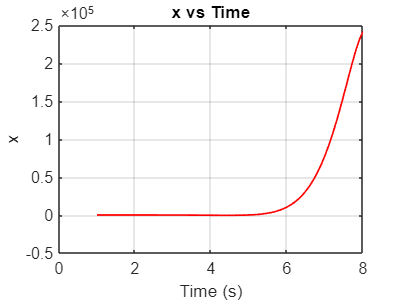



figure;
plot(t,r(:,1),'r','Linewidth', 1) %Plot of x verses time, in red
xlabel('Time (s)');
ylabel('x');
title('x vs Time');
grid on;

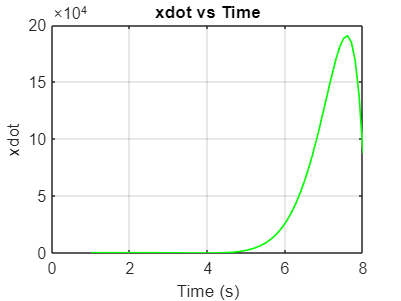


figure;
plot(t,r(:,2),'g','Linewidth', 1) %Plot of xdot verses time in green
xlabel('Time (s)');
ylabel('xdot');
title('xdot vs Time');
grid on;

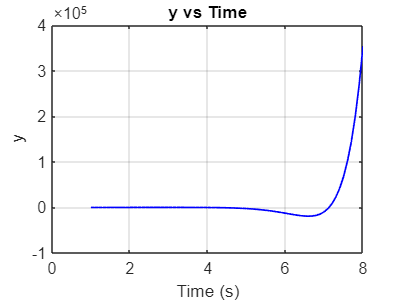


figure;
plot(t,r(:,3),'b','Linewidth', 1)  %Plot of y verses time in blue 

xlabel('Time (s)');
ylabel('y');
title('y vs Time');
grid on;

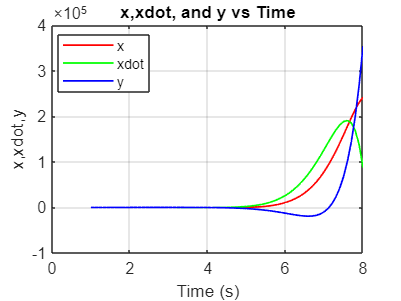


figure;
plot(t,r(:,1),'r','Linewidth', 1)
hold on
plot(t,r(:,2),'g','Linewidth', 1)
hold on
plot(t,r(:,3),'b','Linewidth', 1) 
title('x,xdot, and y vs Time');
xlabel('Time (s)');
ylabel('x,xdot,y');
legend('x', 'xdot', 'y', 'Location', 'best')
grid on;

function drdt = eom(t,r) 

drdt(1) = r(2) ;
drdt(2) = r(2) - 2*r(3) ;
drdt(3) = 2*r(3) + r(1) ;

drdt = drdt' ;

end

